device = serialport("COM4",115200,"Timeout",5)

device =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 115200
                  Tag: ""
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(device,"CR")

readString = "";
complexSpectres = [];
while (1)
    readString = readline(device);
    complexSpectres = [complexSpectres; str2double(split(readString,","))'];
end

Error using split (line 9)
First argument must be text.


clear("device")
S = serialportfind


S =

     []



delete(S)

folder = "Round3\"

folder = "Round3\"

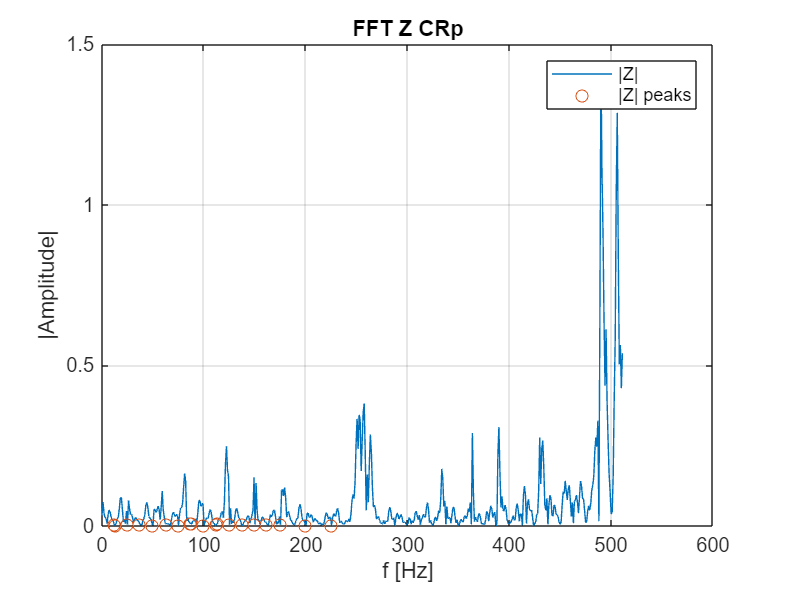


% filename = folder+"complexSpectresLRs.csv";
% filenamePeakIndeces = folder+"LRs.csv";
% filename = folder+"complexSpectresLRp.csv";
% filenamePeakIndeces = folder+"LRp.csv"
% filename = 'complexSpectresCRs1.csv'
% filenamePeakIndeces = 'CRs1.csv'
filename = folder+"complexSpectresCRp.csv";
filenamePeakIndeces = folder+"CRp.csv";

if (exist('complexSpectres','var'))
    writematrix(complexSpectres,filename)
end


% Complex spectres
% complexSpectres.csv - In sign (real,imag), Imp (real, imag), Ref resistor
% sig (real, imag), Uz/Un (real,imag)

FFT_BUFFER_SIZE = 1024;
T = readtable(filename);
Yin_c = T{:,1}+1i*T{:,2};
Yimp_c = T{:,3}+1i*T{:,4};
Yref_c = T{:,5}+1i*T{:,6};
Y_in = abs(Yin_c)*2/FFT_BUFFER_SIZE; % they're maybe single sided - ARM FFT
Y_imp = abs(Yimp_c)*2/FFT_BUFFER_SIZE;
Y_ref = abs(Yref_c)*2/FFT_BUFFER_SIZE;
Y_in(1) = Y_in(1)/2;
Y_imp(1) = Y_imp(1)/2;
Y_ref(1) = Y_ref(1)/2;

% Measured complex
FFT_BUFFER_SIZE = 1024;
Z_c = T{:,7}+1i*T{:,8};
Z = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z(1) = Z(1)/2;

N = 2*length(Z_c);
fs = 1024;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

figure()
plot(f_egy,Z);
title('FFT Z CRp')
% xlim([0,210])

impedanceSpectreAtPeakIndicesRead = readtable(filenamePeakIndeces);
Rn = 1000; %Ohm

% Measured complex plotting
FFT_BUFFER_SIZE = 1024;
T = impedanceSpectreAtPeakIndicesRead{:,:};
f = T(:,1)*fs/FFT_BUFFER_SIZE;
Z_c = (T(:,2)+1i*T(:,3))*Rn;
Z_a = T(:,4);
Z_c_a = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z_fi = angle(Z_c);

hold on
scatter(f,Z_a);
hold off
legend('|Z|','|Z| peaks')
grid on
xlabel('f [Hz]')
ylabel('|Amplitude|')

fig = gcf;
print_figures(fig,"Z_spectrum_CRp",1500,1500,300);

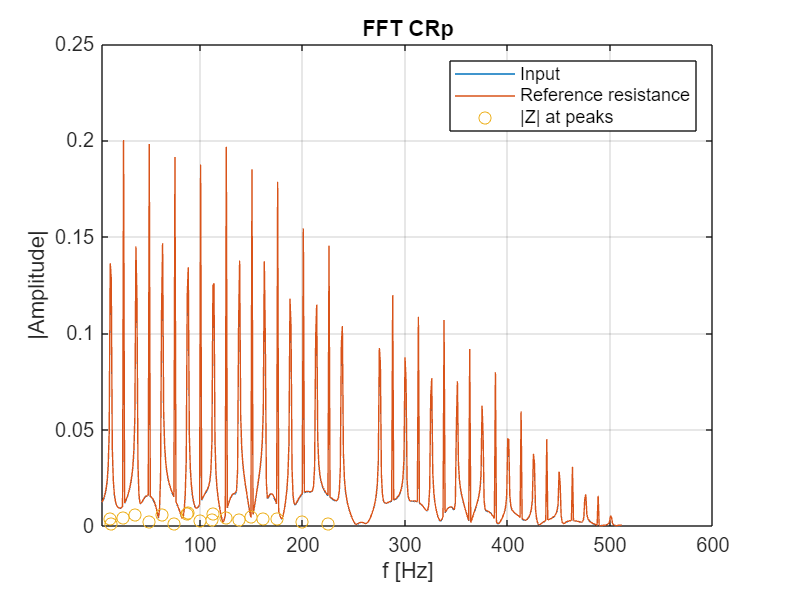


N = 2*length(Yin_c);
fs = 1024;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

figure()
plot(f_egy,Y_in);
hold on
%plot(f_egy,Y_imp);
plot(f_egy,Y_ref);
scatter(T(:,1),Z_a);
hold off
title('FFT CRp')
legend('Input','Reference resistance','|Z| at peaks')
grid on
xlim([4,600])
xlabel('f [Hz]')
ylabel('|Amplitude|')

fig = gcf;
print_figures(fig,"FFT_CRp",1500,1500,300);



clear("complexSpectres")